clear
close all


Part (a)

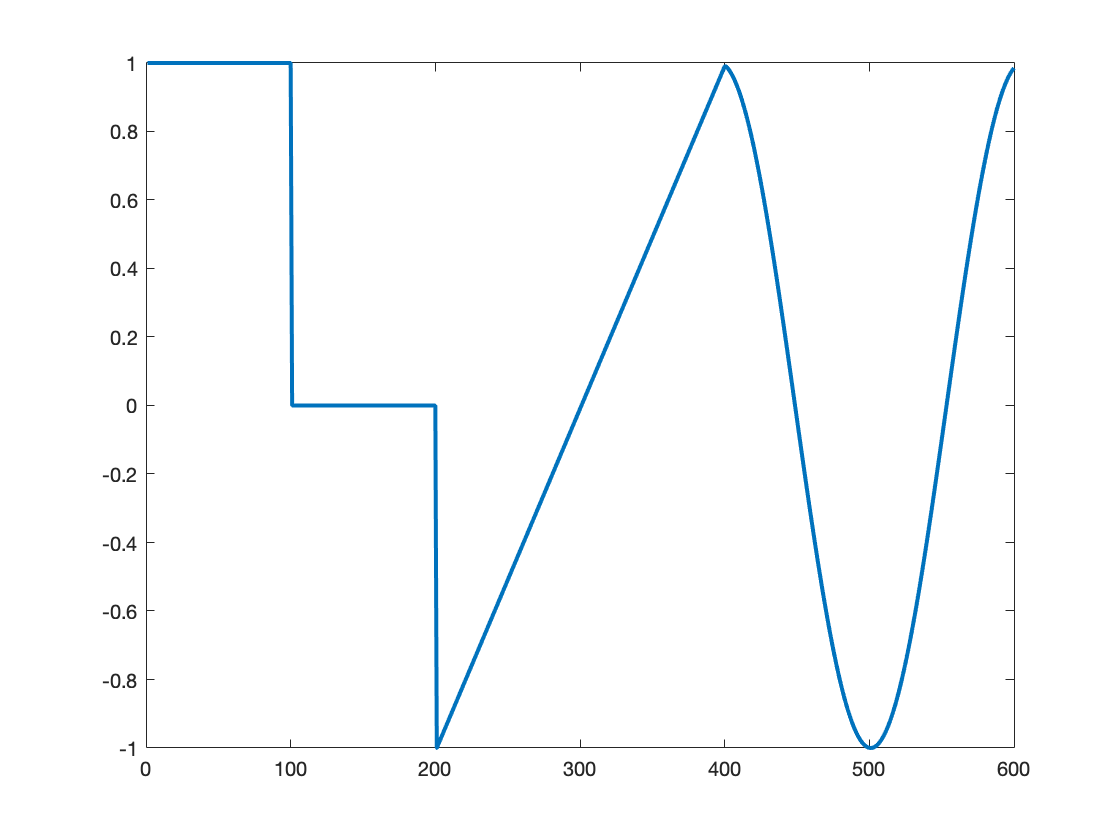

x1 = ones(1,100);
x2 = zeros(1, 100);
x3 = -1:0.01:1-0.01;
x4 = -cos((1:-0.01:-1+0.01)*3);

x = [x1, x2, x3, x4]';

figure(1)
plot(x, 'Linewidth', 2)
axis([0 600 -1 1])

Part (b)

t = (0:0.01:(length(x)-1)*0.01)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Part (c)

y = cos(10*pi*t)

y =     1.0000
    0.9511
    0.8090
    0.5878
    0.3090
    0.0000
   -0.3090
   -0.5878
   -0.8090
   -0.9511


Part (d)

size(x.*y) % This is element mulitplication

ans =    600     1


size(x*y') % This is matrix multiplication between a 600x1 and a 1x600 matrix

ans =    600   600


size(x'*y) % This is matrix multiplication between a 1x600 and a 600x1 matrix

ans =      1     1


The element multiplication has the size of a 600 by 1 matrix because it keeps the size of the 2 matricies that were mutliplied together to create it. The second and third multiplications are depend on the rules of matrix multiplication, making the former (600x1 * 1x600) a 600x600 matrix and the later (1x600 * 600x1) a 1x1 matrix.

Part (e)

z = x.*y;
figure(2)
hold on
plot(x)
plot(z)
legend('x(t)','y(t)')

Part (f)

xd = z ./ y;
norm(xd)

ans = 16.1869

norm(x)

ans = 16.1869

norm(xd) == norm(x) % = 1

ans = logical
   1


Part (g)

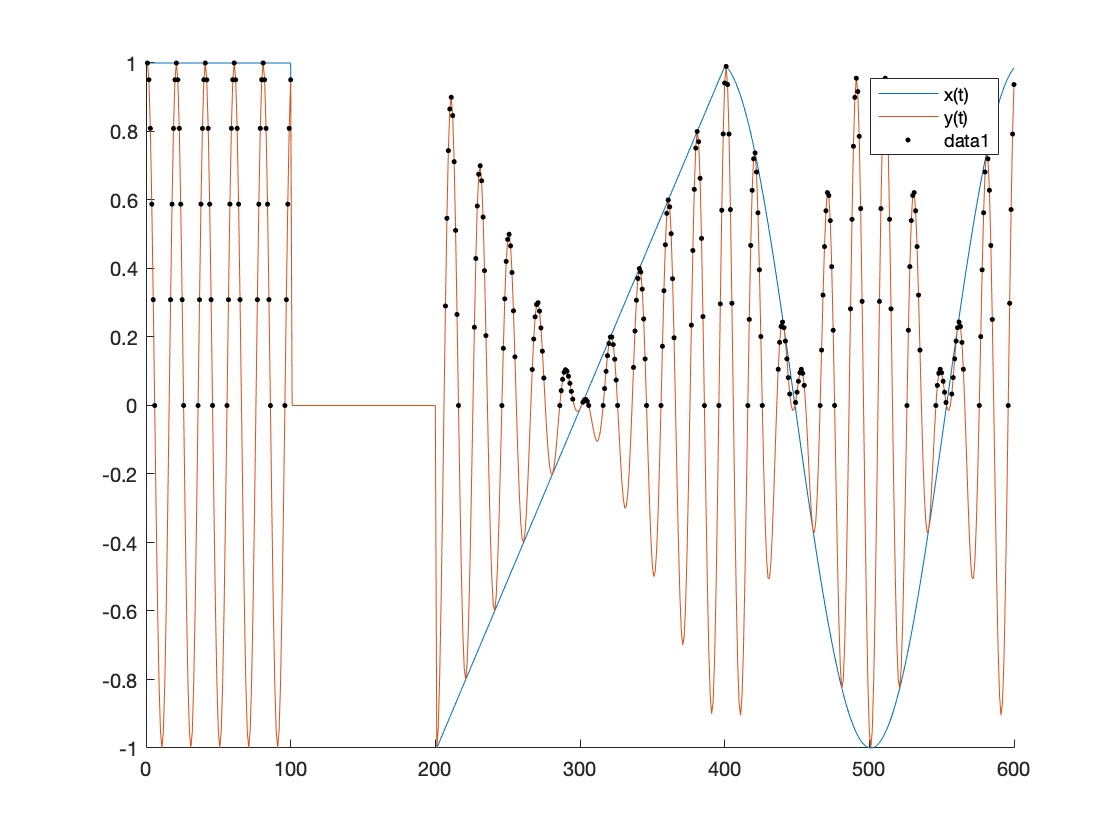

z0 = find(z>0);
z1 = z(z>0);
plot(z0, z1, 'k.')